1 + 1

ans = 2

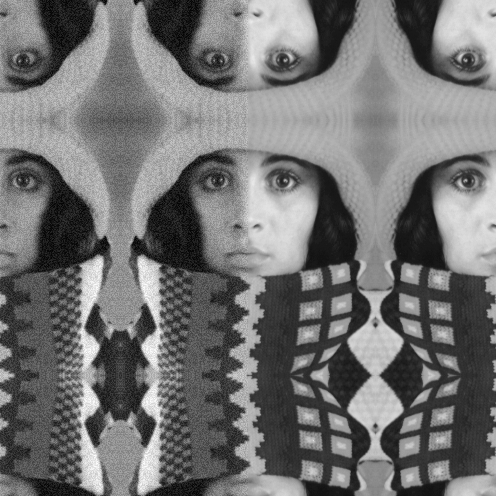

I = readim('truinoise.tif');
dipshow(mat2im(mirroredges(im2mat(I), 120)));

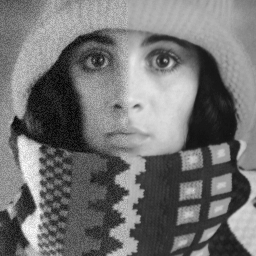

I = readim('truinoise.tif');

dipshow(I);
f = gcf;
f.Name = 'Original image';
f.NumberTitle = 'off';

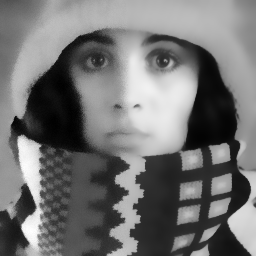


I = double(im2mat(I));
tonalSigma = 50;
spatialSigma = 5;

in = bilateral(I, tonalSigma, spatialSigma);

dipshow(mat2im(in),'lin')
f = gcf;
f.Name = 'Filtered image';
f.NumberTitle = 'off';

I = readim('truinoise.tif');

dipshow(I);
f = gcf;
f.Name = 'Original image';
f.NumberTitle = 'off';

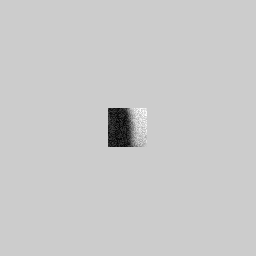

%x1 = 170;
%y1 = 100;
x1 = 60;
y1 = 100;
x2 = x1 + 38;
y2 = y1 + 38;
tile = I(x1:x2, y1:y2);

dipshow(mat2im(tile),'lin')
f = gcf;
f.Name = 'Search tile';
f.NumberTitle = 'off';

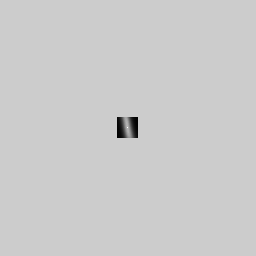

weights = zeros(21, 21);
h = 0.1;
for dy = -10:10
    for dx = -10:10
        tile2 = I((x1:x2) + dx, (y1:y2) + dy);
        tileDiffs = (double(tile2) - double(tile)) ./ 255;
        tileDiffs = mean(tileDiffs .^ 2, 'all');
        weights(dy+11, dx+11) = exp(-tileDiffs ./ h^2);
    end
end
weights = weights ./ sum(weights, 'all');
dipshow(mat2im(weights),'lin')
f = gcf;
f.Name = 'Weight map';
f.NumberTitle = 'off';

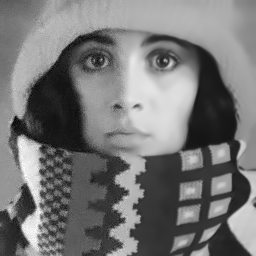

Inlm = readim('truinoise.tif');
Inlm = double(im2mat(Inlm));
h = 0.25;
s = 5;
Inlm = nlm(Inlm, h, s);

dipshow(mat2im(Inlm),'lin')
f = gcf;
f.Name = 'Filtered image';
f.NumberTitle = 'off';